clc
clear all
close all

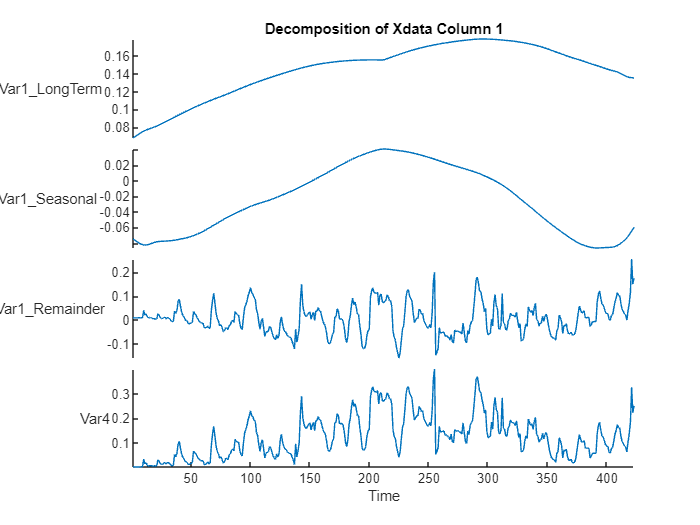


load("WaterQualityData.mat");


T = table(Xdata(:,1));

D = trenddecomp(T,"NumSeasonal",1);
D = addvars(D,Xdata(:,1));

figure
stackedplot(D)
xlabel("Time")
title("Decomposition of Xdata Column 1")

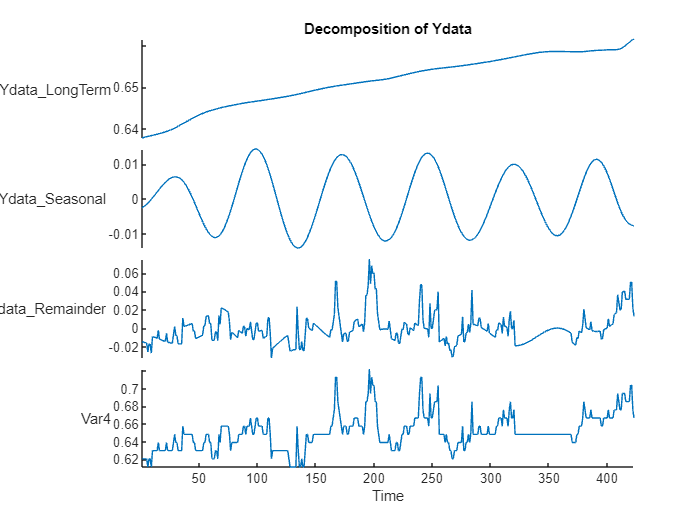

T = table(Ydata);

D = trenddecomp(T);
D = addvars(D,Ydata(:,1));

figure
stackedplot(D)
xlabel("Time")
title("Decomposition of Ydata")

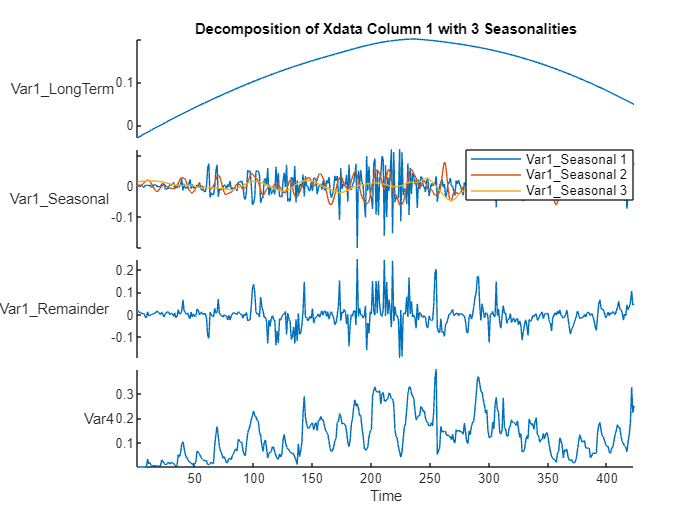


T = table(Xdata(:,1));

D = trenddecomp(T,"stl",[7 30 90]);
D = addvars(D,Xdata(:,1));

figure
stackedplot(D)
xlabel("Time")
title("Decomposition of Xdata Column 1 with 3 Seasonalities")

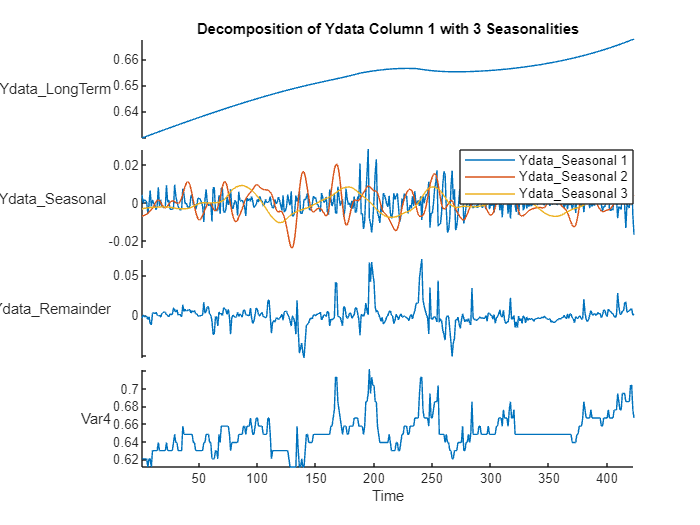


T = table(Ydata);
D = trenddecomp(T,"stl",[7 30 90]);
D = addvars(D,Ydata(:,1));


figure
stackedplot(D)
xlabel("Time")
title("Decomposition of Ydata Column 1 with 3 Seasonalities")

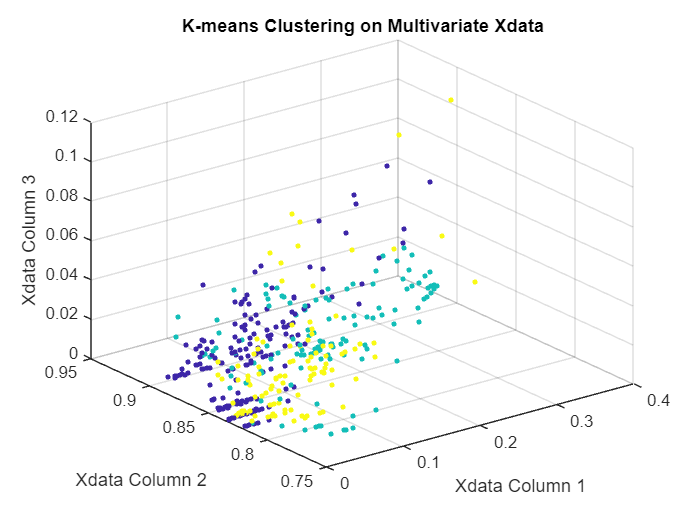


% Assuming Xdata has 10 columns
Y = Xdata;

% Define the number of clusters
num_clusters = 3;

% Apply k-means clustering
idx_kmeans_multivariate = kmeans(Y, num_clusters);

% Plot the results
figure;
scatter3(Y(:, 1), Y(:, 2), Y(:, 3), 10, idx_kmeans_multivariate, 'filled');
title('K-means Clustering on Multivariate Xdata');
xlabel('Xdata Column 1');
ylabel('Xdata Column 2');
zlabel('Xdata Column 3');

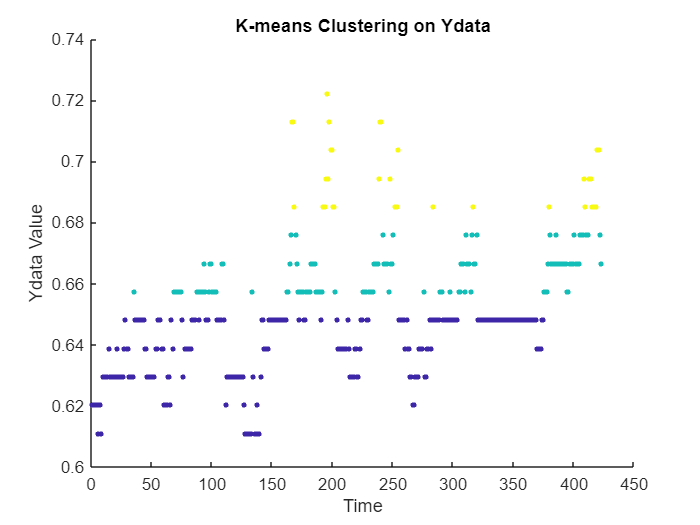

% Assuming Xdata has only one column
Y = Ydata;

% Define the number of clusters
num_clusters = 3; 

% Apply k-means clustering
idx_kmeans = kmeans(Y, num_clusters);

% Plot the results
figure;
scatter(1:length(Y), Y, 10, idx_kmeans, 'filled');
title('K-means Clustering on Ydata');
xlabel("Time")
ylabel('Ydata Value');